# Questão 6

## Para os dados 5

clear;
fileID = fopen('dados_5.txt', 'r');
formatSpec = '\t%f\t%f';
sizeData = [2 Inf];
dados_5 = fscanf(fileID, formatSpec, sizeData);
dados_5 = transpose(dados_5);

Aplicando o algoritmo de mínimos quadrados recursivos com um fator de esquecimento $\lambda =0\ldotp 95$

y_5 = dados_5(:, 1);
u_5 = dados_5(:, 2);
lambda = .95;

% Modelo ARX de ordem 1
[theta1, estimative1] = RLS(1, lambda, y_5, u_5);
error1 = y_5 - estimative1;

% Modelo ARX de ordem 2
[theta2, estimative2] = RLS(2, lambda, y_5, u_5);
error2 = y_5 - estimative2;

% Modelo ARX de ordem 3
[theta3, estimative3] = RLS(3, lambda, y_5, u_5);
error3 = y_5 - estimative3;

% Modelo ARX de ordem 4
[theta4, estimative4] = RLS(4, lambda, y_5, u_5);
error4 = y_5 - estimative4;

% Modelo ARX de ordem 5
[theta5, estimative5] = RLS(5, lambda, y_5, u_5);
error5 = y_5 - estimative5;

Estimação usando modelo ARMAX

% Modelo ARMAX de ordem 1
[theta1x, estimative1x] = RLS(1, lambda, y_5, u_5, error1);
error1x = y_5 - estimative1x;

% Modelo ARMAX de ordem 2
[theta2x, estimative2x] = RLS(2, lambda, y_5, u_5, error2);
error2x = y_5 - estimative2x;

% Modelo ARMAX de ordem 3
[theta3x, estimative3x] = RLS(3, lambda, y_5, u_5, error3);
error3x = y_5 - estimative3x;

% Modelo ARMAX de ordem 4
[theta4x, estimative4x] = RLS(4, lambda, y_5, u_5, error4);
error4x = y_5 - estimative4x;

% Modelo ARMAX de ordem 5
[theta5x, estimative5x] = RLS(5, lambda, y_5, u_5, error5);
error5x = y_5 - estimative5x;

Validação

epsilon = length(y_5)/2;
[estimative1v, error1v] = rvalidate(theta1, epsilon, y_5, u_5);
[estimative2v, error2v] = rvalidate(theta2, epsilon, y_5, u_5);
[estimative3v, error3v] = rvalidate(theta3, epsilon, y_5, u_5);
[estimative4v, error4v] = rvalidate(theta4, epsilon, y_5, u_5);
[estimative5v, error5v] = rvalidate(theta5, epsilon, y_5, u_5);

Comparativo erros de estimação

error = [mean(error1.^2), mean(error1v.^2), mean(error1x.^2)];
error = [error; mean(error2.^2), mean(error2v.^2), mean(error2x.^2)];
error = [error; mean(error3.^2), mean(error3v.^2), mean(error3x.^2)];
error = [error; mean(error4.^2), mean(error4v.^2), mean(error4x.^2)];
error = [error; mean(error5.^2), mean(error5v.^2), mean(error5x.^2)];
error

error =     0.2134    0.1917    0.2103
    0.1930    0.1766    0.1915
    0.1735    0.1655    0.1725
    0.1760    0.1671    0.1760
    0.1769    0.1671    0.1773


O modelo escolhido foi o modelo 4

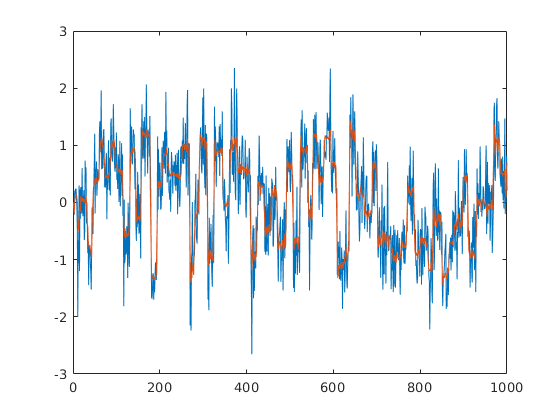

plot(y_5);
hold on;
plot(estimative4x);
hold off;

É possível descrever a evolução do theta

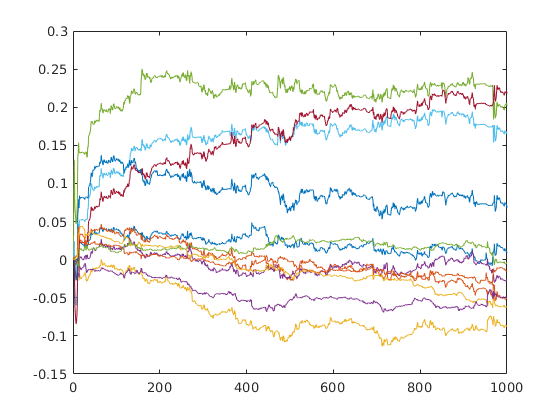

for k = 1:4*3
    plot(theta4x(:, k));
    hold on;
end
hold off;

## Para os dados 6

clear;
fileID = fopen('dados_6.txt', 'r');
formatSpec = '\t%f\t%f';
sizeData = [2 Inf];
dados_6 = fscanf(fileID, formatSpec, sizeData);
dados_6 = transpose(dados_6);

Aplicando o algoritmo de mínimos quadrados recursivos com um fator de esquecimento $\lambda =0\ldotp 95$

y_6 = dados_6(:, 1);
u_6 = dados_6(:, 2);
lambda = .95;

% Modelo ARX de ordem 1
[theta1, estimative1] = RLS(1, lambda, y_6, u_6);
error1 = y_6 - estimative1;

% Modelo ARX de ordem 2
[theta2, estimative2] = RLS(2, lambda, y_6, u_6);
error2 = y_6 - estimative2;

% Modelo ARX de ordem 3
[theta3, estimative3] = RLS(3, lambda, y_6, u_6);
error3 = y_6 - estimative3;

% Modelo ARX de ordem 4
[theta4, estimative4] = RLS(4, lambda, y_6, u_6);
error4 = y_6 - estimative4;

% Modelo ARX de ordem 5
[theta5, estimative5] = RLS(5, lambda, y_6, u_6);
error5 = y_6 - estimative5;

Estimação usando modelo ARMAX

% Modelo ARMAX de ordem 1
[theta1x, estimative1x] = RLS(1, lambda, y_6, u_6, error1);
error1x = y_6 - estimative1x;

% Modelo ARMAX de ordem 2
[theta2x, estimative2x] = RLS(2, lambda, y_6, u_6, error2);
error2x = y_6 - estimative2x;

% Modelo ARMAX de ordem 3
[theta3x, estimative3x] = RLS(3, lambda, y_6, u_6, error3);
error3x = y_6 - estimative3x;

% Modelo ARMAX de ordem 4
[theta4x, estimative4x] = RLS(4, lambda, y_6, u_6, error4);
error4x = y_6 - estimative4x;

% Modelo ARMAX de ordem 5
[theta5x, estimative5x] = RLS(5, lambda, y_6, u_6, error5);
error5x = y_6 - estimative5x;

Validação

epsilon = length(y_6)/2;
[estimative1v, error1v] = rvalidate(theta1, epsilon, y_6, u_6);
[estimative2v, error2v] = rvalidate(theta2, epsilon, y_6, u_6);
[estimative3v, error3v] = rvalidate(theta3, epsilon, y_6, u_6);
[estimative4v, error4v] = rvalidate(theta4, epsilon, y_6, u_6);
[estimative5v, error5v] = rvalidate(theta5, epsilon, y_6, u_6);

Comparativo erros de estimação

error = [mean(error1.^2), mean(error1v.^2), mean(error1x.^2)];
error = [error; mean(error2.^2), mean(error2v.^2), mean(error2x.^2)];
error = [error; mean(error3.^2), mean(error3v.^2), mean(error3x.^2)];
error = [error; mean(error4.^2), mean(error4v.^2), mean(error4x.^2)];
error = [error; mean(error5.^2), mean(error5v.^2), mean(error5x.^2)];
error

error =     0.1562    0.2301    0.1242
    0.1542    0.1897    0.1506
    0.1912    0.2139    0.1900
    0.2103    0.2232    0.2130
    0.2268    0.2373    0.2316


O modelo escolhido foi o modelo 2

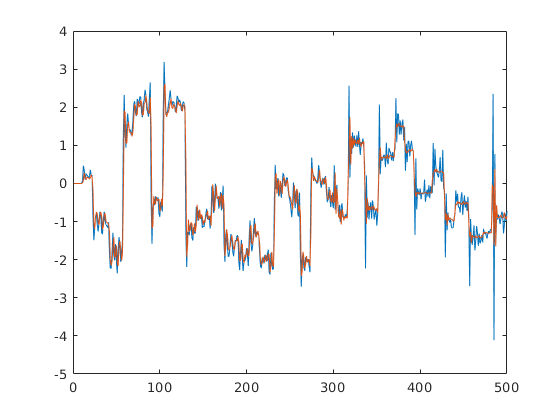

plot(y_6);
hold on;
plot(estimative2x);
hold off;

É possível descrever a evolução do theta

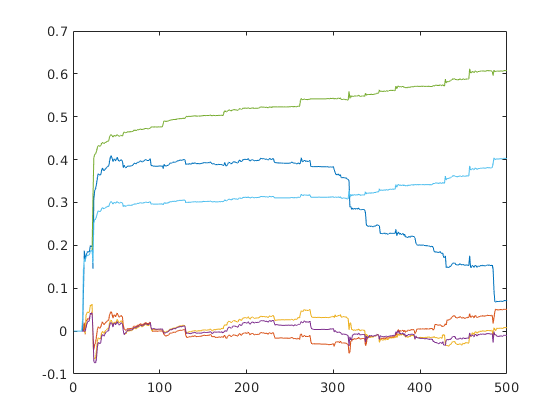

for k = 1:2*3
    plot(theta4x(:, k));
    hold on;
end
hold off;